clear all;
clc;

## `Auto Encoder Modelling:`

### Create a dataset of random binary data sequences for training and testing. 

% Generate random binary data
num_samples = 100000;
sequence_length = 150;

dataset = cell(1, num_samples);

for i = 1:num_samples
    dataset{i} = randi([0, 1], 1, sequence_length);   
end
% Example: Accessing a specific sequence
sample_index = 18;
data_sequence = dataset{sample_index};
% Convert cell arrays to matrices
datasetMatrix = cell2mat(dataset');

#### Spliting train and test data:

% Specify the percentage of data for training
trainPercentage = 90; % Adjust as needed

% Create a random partition for training and testing
cv = cvpartition(size(datasetMatrix, 1), 'HoldOut', 1 - trainPercentage/100);

% Split the data into training and test sets
trainData = datasetMatrix(training(cv), :);
testData = datasetMatrix(test(cv), :);


### Define an autoencoder architecture:

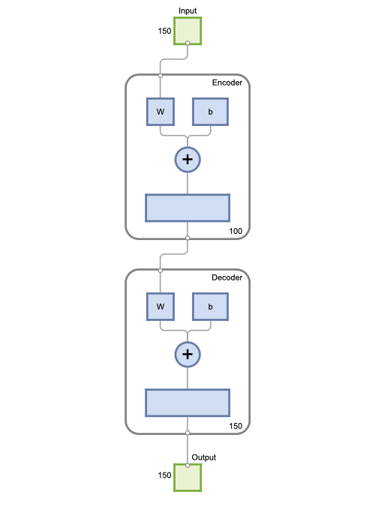

input_size = sequence_length;
hidden_size = 100; % Adjust the number of hidden units as needed

autoencoder = trainAutoencoder(trainData', hidden_size, 'MaxEpochs', 100, 'EncoderTransferFunction', 'logsig', 'DecoderTransferFunction', 'logsig');
view(autoencoder)

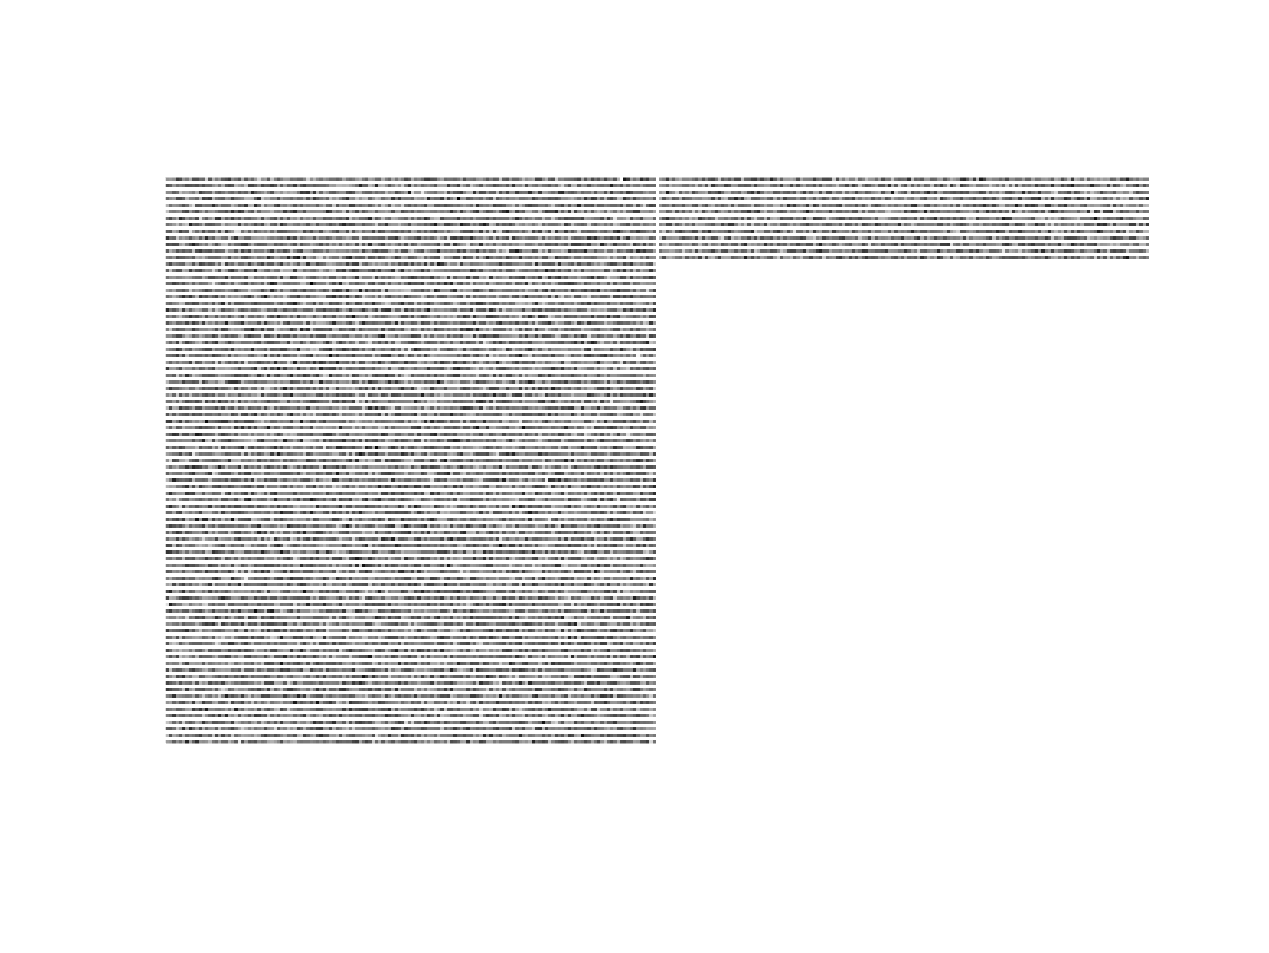

ans =   Image with properties:

           CData: [173x301 double]
    CDataMapping: 'scaled'

  Show all properties


figure()
plotWeights(autoencoder)

###  Encode and decode data using the trained autoencoder:

encoded_data = encode(autoencoder, data_sequence');
decoded_data = decode(autoencoder, encoded_data)';

% Display the results or perform further analysis
disp('Original Data:');

Original Data:


disp(data_sequence);

     1     1     1     0     1     1     1     1     1     1     0     1     1     0     0     1     0     0     0     1     1     1     0     1     0     0     1     0     0     1     1     1     0     1     1     0     1     0     1     0     0     0     1     0     0     0     1     1     0     0     1     0     1     0     1     1     1     1     0     1     1     1     1     0     1     0     0     1     0     1     0     0     0     1     0     0     0     1     1     1     1     0     1     1     0     0     0     1     1     0     1     0     1     1     1     1     0     0     0     1     1     1     0     0     0     1     0     0     1     0     0     1     0     1     0     1     0     1     1     0     1     0     0     0     1     1     0     1     1     1     0     0     1     1     1     0     1     0     1     0     1     1     1     0     1     0     0     1     0     0



disp('Decoded Data:');

Decoded Data:


disp(decoded_data);

    0.6482    0.5824    0.4877    0.4459    0.4801    0.4688    0.5768    0.6328    0.7234    0.7338    0.4033    0.5933    0.6278    0.5339    0.5193    0.7698    0.5069    0.5053    0.5706    0.4933    0.5811    0.6383    0.4447    0.6982    0.3201    0.5457    0.4557    0.5388    0.4550    0.4925    0.6216    0.6101    0.3224    0.6999    0.5687    0.4994    0.7023    0.3859    0.5609    0.5639    0.3997    0.5315    0.7293    0.3292    0.2575    0.3897    0.6315    0.6267    0.4416    0.5856    0.5836    0.4690    0.7183    0.3456    0.5039    0.7524    0.5016    0.6695    0.4173    0.4666    0.5491    0.6813    0.5131    0.3363    0.5532    0.4024    0.4119    0.6859    0.3346    0.5332    0.4426    0.5338    0.4808    0.5979    0.3669    0.4239    0.5229    0.6100    0.5661    0.5506    0.6779    0.5166    0.5035    0.5674    0.3611    0.3294    0.4641    0.6273    0.5761    0.4590    0.4125    0.6163    0.7172    0.6784    0.3610    0.5069    0.4276    0.4382    0.3403    0.5761

###  Encode and decode test data using the trained autoencoder:

encoded_test_data = encode(autoencoder, testData');
decoded_test_data = decode(autoencoder, encoded_test_data)';

### MSE and PSNR for Test data:

% Compute Mean Squared Error (MSE)
mse = immse(testData, decoded_test_data);
disp(['Mean Squared Error on Test Data: ', num2str(mse)]);

Mean Squared Error on Test Data: 0.17607


% Evaluate PSNR
psnrValue = psnr(decoded_test_data, testData);
disp(['PSNR on Test Data: ', num2str(psnrValue)]);

PSNR on Test Data: 7.5431


### Channel with AWGN noise + Rayleigh fading:

% Define channel parameters
SNR_dB = 10; % Signal-to-Noise Ratio in dB
SNR = 10^(SNR_dB/10); % Convert dB to linear scale
channel_coefficient = 1; % Channel coefficient (can represent fading)

% Generate random binary data
num_bits = 150;
data = randi([0, 1], 1, num_bits);

% Modulate the data (e.g., BPSK modulation)
modulated_data = 2 * data - 1;
encoded_data_channel = encode(autoencoder, data')';

% Add AWGN noise
noise = sqrt(1 / (2 * SNR)) * randn(1, hidden_size);

% Rayleigh fading
fading_channel = (1/sqrt(2)) * (randn(1, hidden_size) + 1i * randn(1, hidden_size));


% Simulate wireless transmission through the channel
transmitted_signal = channel_coefficient * encoded_data_channel; % You may include modulation if needed
% received_signal = awgn(transmitted_signal, SNR_dB); % Add AWGN noise
received_signal_with_fading = fading_channel .* transmitted_signal;
received_signal = channel_coefficient *  transmitted_signal + noise;

% Decode the received signal using the trained autoencoder
decoded_data = decode(autoencoder, received_signal');
decoded_data_2 = (real(decoded_data) > 0.5);
disp(data)

     0     0     0     1     0     1     1     1     1     0     0     1     1     0     1     0     0     0     0     1     1     0     1     1     0     0     0     1     1     0     0     1     1     1     0     0     1     0     1     1     1     1     1     1     0     0     1     1     1     0     0     1     0     0     1     0     1     1     1     1     1     0     1     0     1     1     1     0     0     0     0     1     1     0     1     0     1     1     1     0     0     0     0     0     1     1     1     1     1     1     0     0     1     0     0     1     0     0     1     1     1     0     0     1     0     1     1     1     1     1     0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     1     1     0     1     0     1     1     0     1     1     1     0     1     1     1     1     0     1     1     0     0



### MSE for Channel decoded signal:

mse = immse(data, decoded_data');
disp(['Mean Squared Error on channel Data: ', num2str(mse)]);

Mean Squared Error on channel Data: 0.23039


### BER for Channel decoded signal:

% Compare Transmitted and Received Bits
incorrect_bits = sum(data ~= decoded_data_2');

% Calculate Bit Error Rate (BER)
BER = incorrect_bits / num_bits;

disp(['Bit Error Rate (BER): ', num2str(BER)]);

Bit Error Rate (BER): 0.34
